Questions: 

- A practical question: it is possible that some brain regions don't have connections between each other. 

- How do we guarantee that the basis of each individual adj matrix include the same number of columns. Do we make assumption about the rank of the matrices?

S = load('RSgammaEnvCorr.mat');
adj = S.data;

% get the adj matrix size for each participant
s = size(adj);
size_cell = zeros(49,3);

for i = 1:s(2)
    for j = 1:3
    adj_mat = getfield(adj(i), 'Adj');
    adj_mat_size = size(adj_mat);
    size_cell(i,j) = adj_mat_size(1,j);
    end
end

size_cell

size_cell =    210   210    10
    23    23    11
    93    93    10
   190   190    10
   144   144    10
   184   184    10
   201   201    10
    91    91    10
   212   212    13
    78    78    10


% average over time, and replace nan with 1's
adj_mat_all = {};
for idx = 1:size(adj,2)
    current_adj_mat = adj(idx).Adj;
    ave = mean(current_adj_mat, 3);
    ave(isnan(ave))=1;
    adj_mat_all{end+1} = ave;
end

adj_mat_all{3}

ans =     1.0000    0.0882    0.0690    0.1029    0.0434    0.1122    0.3810    0.1757    0.3658    0.3807    0.3414    0.3098    0.1039    0.1217    0.2271    0.2024    0.3718    0.4923    0.1946    0.1537    0.0303    0.1958    0.2279    0.2195    0.2761    0.4444    0.3247    0.1301    0.0548    0.0603    0.0520    0.1719    0.2269    0.2422    0.2268    0.2119    0.2215    0.0995    0.2026    0.1009    0.4225    0.4524    0.3862    0.3831    0.5786    0.2084    0.1812    0.2442    0.2090    0.2258
    0.0882    1.0000    0.1077    0.1133    0.0539    0.1075    0.3682    0.1731    0.4073    0.3951    0.3996    0.3380    0.1169    0.1489    0.2254    0.2114    0.4223    0.4962    0.1786    0.1575    0.0339    0.2020    0.2460    0.2484    0.2755    0.4350    0.3324    0.1350    0.0530    0.0980    0.0576    0.1765    0.2521    0.2661    0.2521    0.2610    0.2562    0.0991    0.2080    0.0996    0.4675    0.5042    0.4388    0.3959    0.5957    0.2043    0.1721    0.2495    0.2942   

% find the union of all label
total_labels = [];

for i = 1:49
    x = adj(i).ROI;
    for j = 1:size(x,2)
        if ismember(x{j}, total_labels) == 0
            total_labels =[total_labels, string(x{j})];
        end
    end
end

total_labels

total_labels = 1×58 string array
    "HGPM"    "HGAL"    "STGP"    "STGM"    "STGA"    "MTGP"    "MTGM"    "MTGA"    "SMG"    "IFGop"    "IFGtr"    "MFG"    "SFG"    "OG"    "TFG"    "dPostCG"    "vPreCG"    "vPostCG"    "PMC"    "FG"    "ITGP"    "ITGM"    "ITGA"    "TP"    "GR"    "MOG"    "Amyg"    "Hipp"    "InsP"    "STSU"    "fOperc"    "Put"    "AGA"    "AGP"    "CingM"    "PCCpreCun"    "SPL"    "SOG"    "PP"    "dPreCG"    "PHG"    "InsA"    "ACC"    "SubcG"    "LingG"    "IFGor"    "ParaCL"    "PT"    "pOperc"    "STSL"    "IOG"    "FMG"    "Caud"    "OP"    "SubInn"    "vStriatum"    "Cun"    "GP"


% inflate matrix with -1 when they don't have signals on certain ROIs,take
% average if one region was observed multiple times
inf_adjMat = {};
ind_adjMat = zeros(length(total_labels), length(total_labels));

for idx = 1:49
    for i = 1:length(total_labels)
        for j = 1:length(total_labels)
            if ismember(total_labels(i), adj(idx).ROI) == 0 || ismember(total_labels(j), adj(idx).ROI) == 0
                ind_adjMat(i,j) = -1;
            else
                ori_idx_1 = find(adj(idx).ROI == total_labels(i),1);
                ori_idx_2 = find(adj(idx).ROI == total_labels(j),1);
                ind_adjMat(i,j) = adj_mat_all{idx}(ori_idx_1, ori_idx_2);
            end
        end
    end
    inf_adjMat{end+1} = ind_adjMat;
end

omega = [];
sum_mat = [];
for idx = 1:49
    for i = 1:length(total_labels)
        for j = 1:length(total_labels)
            sum_mat(i,j) = sum(i,j) + inf_adjMat{idx}(i,j);
        end
    end
end

for i = 1:length(total_labels)
    for j = 1:length(total_labels)
        if sum_mat(i,j) == -49
            omega(i,j) = 0;
        else
            omega(i,j) = 1;
        end
    end
end

omega

omega =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     

ROI_count = zeros(length(total_labels),length(total_labels));
for i = 1:length(total_labels)
    for j = 1:length(total_labels)
        for idx = 1:49
            if inf_adjMat{idx}(i,j) ~= -1
                ROI_count(i,j) = ROI_count(i,j)+ 1;
            end
        end
    end
end

ROI_count

ROI_count =     38    30    32    34    26    33    34    30    34    30    31    35    17    35    17    16    34    31    33    29    22    27    26    30    28    14    28    25    30    19    13     8    24    11    14    14     9     1    25    24    23    26    21     3     9    15     4    21     6    19
    30    30    28    29    23    28    27    24    27    25    25    29    14    28    16    13    26    24    27    25    20    24    22    27    23    11    24    20    23    15    12     5    20     9    10     7     5     1    20    20    21    20    14     1     5    11     3    17     3    14
    32    28    37    34    26    35    33    28    34    32    31    32    17    33    18    19    32    31    34    31    24    29    28    32    25    16    25    23    26    17    12     6    27    15    15    13    12     4    21    24    26    22    17     3     9    16     2    19     5    20
    34    29    34    36    26    33    33    27    34    30    30    32    16    34 

count = 0

count = 0

s = size(ROI_count)

s =     58    58


for i = 1:s(1)
    for j = 1:s(2)
        if ROI_count(i,j) == 0
            count = count + 1;
        end
    end
end

count

count = 226

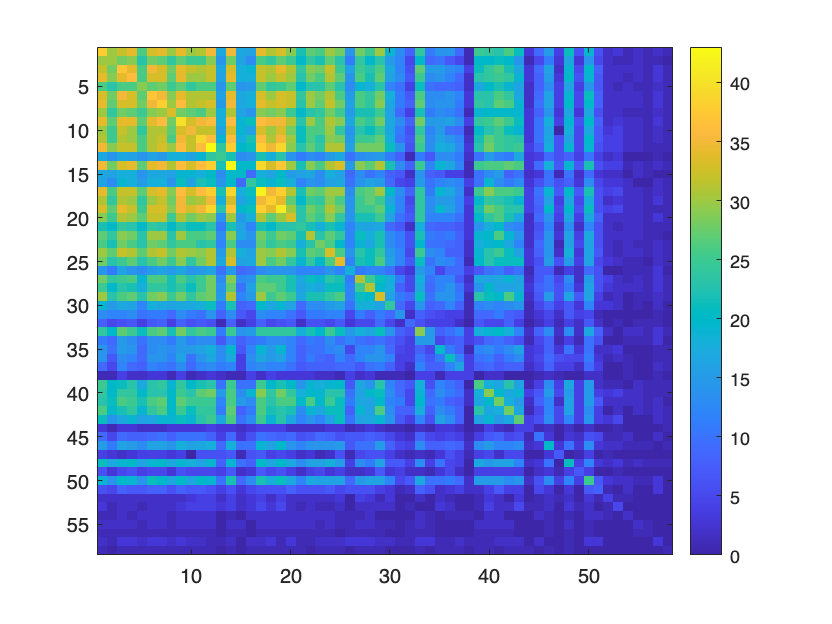

imagesc(ROI_count)
colorbar

% ave over ROIs
adj_aveROI ={}


adj_aveROI =

  0×0 empty cell array



obj_list = []


obj_list =

     []



for i = 1:49
    obj_list = [obj_list, avgByROI(adj(i), total_labels)];
    cur_obj = getfield(obj_list(i), 'Adj');
    ave = mean(cur_obj, 3);
    adj_aveROI{end+1} = ave;    
end

save('adjdata.mat', "adj_aveROI")